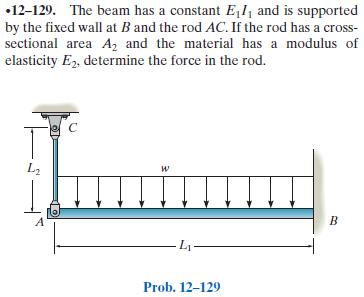

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-129P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-129P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
E1 = sym('E1');
I1 = sym('I1');
L1 = sym('L1', 'positive');
Fac = sym('Fac');
E2 = sym('E2');
A2 = sym('A2');
L2 = sym('L2');

# beam

b = beam;
b = b.add('reaction', 'force', 'Rb', L1);
b = b.add('reaction', 'moment', 'Mb', L1);
b = b.add('concentrated', 'force', Fac, 0);
b = b.add('distributed', 'force', -wo, [0 L1]);
b.L = L1;

# section properties

b.E = E1;
b.I = I1;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = -\frac{{\left(L_{1}-x\right)}^{2}\,\left(3\,\mathrm{wo}\,{L_{1}}^{2}+2\,\mathrm{wo}\,L_{1}\,x-8\,\mathrm{Fac}\,L_{1}+\mathrm{wo}\,x^{2}-4\,\mathrm{Fac}\,x\right)}{24\,E_{1}\,I_{1}}$$

dy

$$dy(x) = \frac{\left(L_{1}-x\right)\,\left(\mathrm{wo}\,{L_{1}}^{2}+\mathrm{wo}\,L_{1}\,x-3\,\mathrm{Fac}\,L_{1}+\mathrm{wo}\,x^{2}-3\,\mathrm{Fac}\,x\right)}{6\,E_{1}\,I_{1}}$$

m

$$m(x) = \frac{x\,\left(2\,\mathrm{Fac}-\mathrm{wo}\,x\right)}{2}$$

v

$$v(x) = \mathrm{Fac}-\mathrm{wo}\,x$$

w

$$w(x) = -\mathrm{wo}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Mb} & \frac{L_{1}\,\left(2\,\mathrm{Fac}-L_{1}\,\mathrm{wo}\right)}{2}\\ \mathrm{Rb} & L_{1}\,\mathrm{wo}-\mathrm{Fac} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

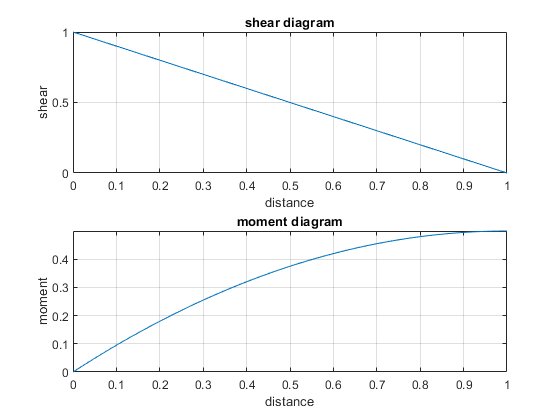

beam.shear_moment(m, v, [0 1], [wo E1 I1 L1 Fac], 1);

# force in rod AC

Fac(wo, E1, I1, L1, E2, A2, L2) = simplify(solve(y(0) == -Fac*L2/(A2*E2), Fac))

$$Fac(wo, E1, I1, L1, E2, A2, L2) = \frac{3\,A_{2}\,E_{2}\,{L_{1}}^{4}\,\mathrm{wo}}{8\,A_{2}\,E_{2}\,{L_{1}}^{3}+24\,E_{1}\,I_{1}\,L_{2}}$$

# clean up

addvar(y);
new_assum = assumptions;